## Problem 1

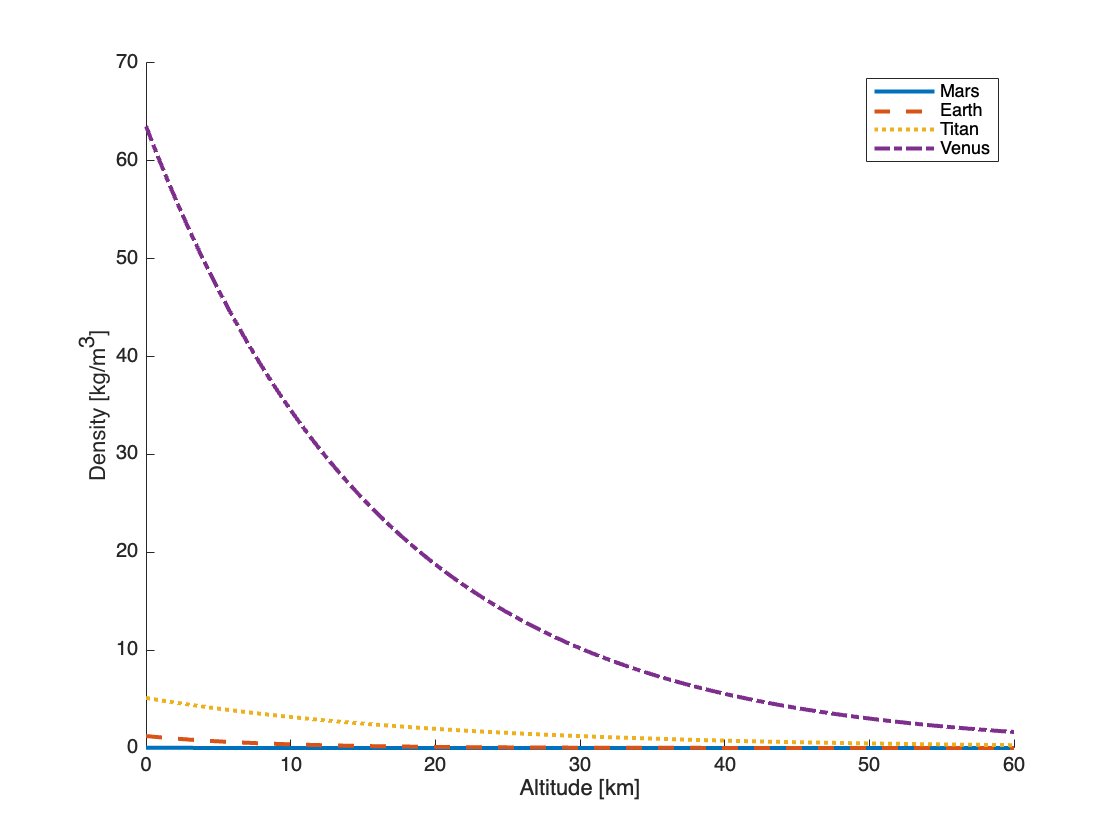

%CONSTANTS
R = 8.315; %J/K-mol
M_CO2 = 2*15.999e-3 + 12.011e-3; %kg/mol
M_N2 = 2*14.007e-3; %kg/mol
M_O2 = 2*15.999e-3; %kg/mol
M_AR = 39.948e-3; %kg/mol
h = linspace(0,60,1000); %km

%MARS
P = 651.8; %Pa
T = (-120 - 32)*5/9 + 273.15; %K
g = 3.71; %m/s^2
M = 0.9532*M_CO2 + 0.027*M_N2 + 0.016*M_AR; %kg/mol
H_mars = R*T/(M*g)/1000; %km
rho0 = P*M/(R*T); %kg/m^3
rho_mars = rho0*exp(-h/H_mars); %kg/m^3

%EARTH
P = 101325; %Pa
T = 288; %K
g = 9.81; %m/s^2
M = 0.78084*M_N2 + 0.20946*M_O2 + 0.00934*M_AR; %kg/mol
H_earth = R*T/(M*g)/1000; %km
rho0 = P*M/(R*T); %kg/m^3
rho_earth = rho0*exp(-h/H_earth); %kg/m^3

%TITAN
P = 146.7e3; %Pa
T = 93.7; %K
g = 0.14*9.81; %m/s^2
M = 0.97*M_N2; %kg/mol
H_titan = R*T/(M*g)/1000; %km
rho0 = P*M/(R*T); %kg/m^3
rho_titan = rho0*exp(-h/H_titan); %kg/m^3

%VENUS
P = 92 * 100000; %Pa
T = 470 + 273.15; %K
g = 0.9*9.81; %m/s^2
M = 0.97*M_CO2; %kg/mol
H_venus = R*T/(M*g)/1000; %km
rho0 = P*M/(R*T); %kg/m^3
rho_venus = rho0*exp(-h/H_venus); %kg/m^3

figure();
hold on
plot(h,rho_mars,'-','LineWidth',2)
plot(h,rho_earth,'--','LineWidth',2)
plot(h,rho_titan,':','LineWidth',2)
plot(h,rho_venus,'-.','LineWidth',2)
xlabel('Altitude [km]')
ylabel('Density [kg/m^3]')
legend('Mars','Earth','Titan','Venus')
hold off

fprintf("Scale Heights\nMars: %.4f [km]\nEarth: %.4f [km]\nTitan: %.4f [km]\nVenus: %.4f [km]", H_mars, H_earth, H_titan, H_venus)

Scale Heights
Mars: 9.7574 [km]
Earth: 8.4322 [km]
Titan: 20.8765 [km]
Venus: 16.3951 [km]

## Problem 2

P = 101325; %Pa
T = 288; %K
g_earth = 9.81; %m/s^2
M = 0.78084*M_N2 + 0.20946*M_O2 + 0.00934*M_AR; %kg/mol
H_earth = R*T/(M*g_earth); %m
A_earth = 1/H_earth; %1/m
rho0_earth = P*M/(R*T); %kg/m^3

P = 651.8; %Pa
T = (-120 - 32)*5/9 + 273.15; %K
g = 3.71; %m/s^2
M = 0.9532*M_CO2 + 0.027*M_N2 + 0.016*M_AR; %kg/mol
H_mars = R*T/(M*g); %m
A_mars = 1/H_mars; %1/m
rho0_mars = P*M/(R*T); %kg/m^3

beta1 = 45.8/(1.8*pi/4*0.827^2) %kg/m^2

beta1 = 47.3688

beta2 = 980/(1.65*pi/4*3.54^2) %kg/m^2

beta2 = 60.3456

#### (a) $\beta_{Stardust} = 47.37 \frac{kg}{m^2}$ & $\beta_{Viking} = 60.35 \frac{kg}{m^2}$

nmax1 = (12.8e3)^2*A_earth*sind(-8.2)/(2*9.81*exp(1)) %g

nmax1 = -51.9631

nmax2 = (4.61e3)^2*A_mars*sind(-17)/(2*9.81*exp(1)) %g

nmax2 = -11.9401

#### (b) $n_{max, Stardust} = -51.963 g$ & $n_{max, Viking} = -11.94 g$

vnmax1 = 0.606*12.8e3 %m/s

vnmax1 = 7.7568e+03

vnmax2 = 0.606*4.61e3 %m/s

vnmax2 = 2.7937e+03

#### (c) $V_{n,Stardust} = 7.7568 \frac{km}{s}$ & $V_{n,Viking} = 2.7937 \frac{km}{s}$

hnmax1 = H_earth*log(-rho0_earth/(beta1*A_earth*sind(-8.2))) %km

hnmax1 = 6.1827e+04

hnmax2 = H_mars*log(-rho0_mars/(beta2*A_mars*sind(-17))) %km

hnmax2 = 2.2426e+04

#### (d) $h_{n,Stardust} = 61.83 km$ & $h_{n,Viking} = 22.43 km$

sn1 = cotd(-8.2)*(85e3 - hnmax1)/1000 %km

sn1 = -160.8123

sn2 = cotd(-17)*(80e3 - hnmax2)/1000 %km

sn2 = -188.3163

#### (e) $\Delta s_{n,Stardust} = -160.8 km$ & $\Delta s_{n, Viking} = -188.3 km$

#### (f) See below graphs

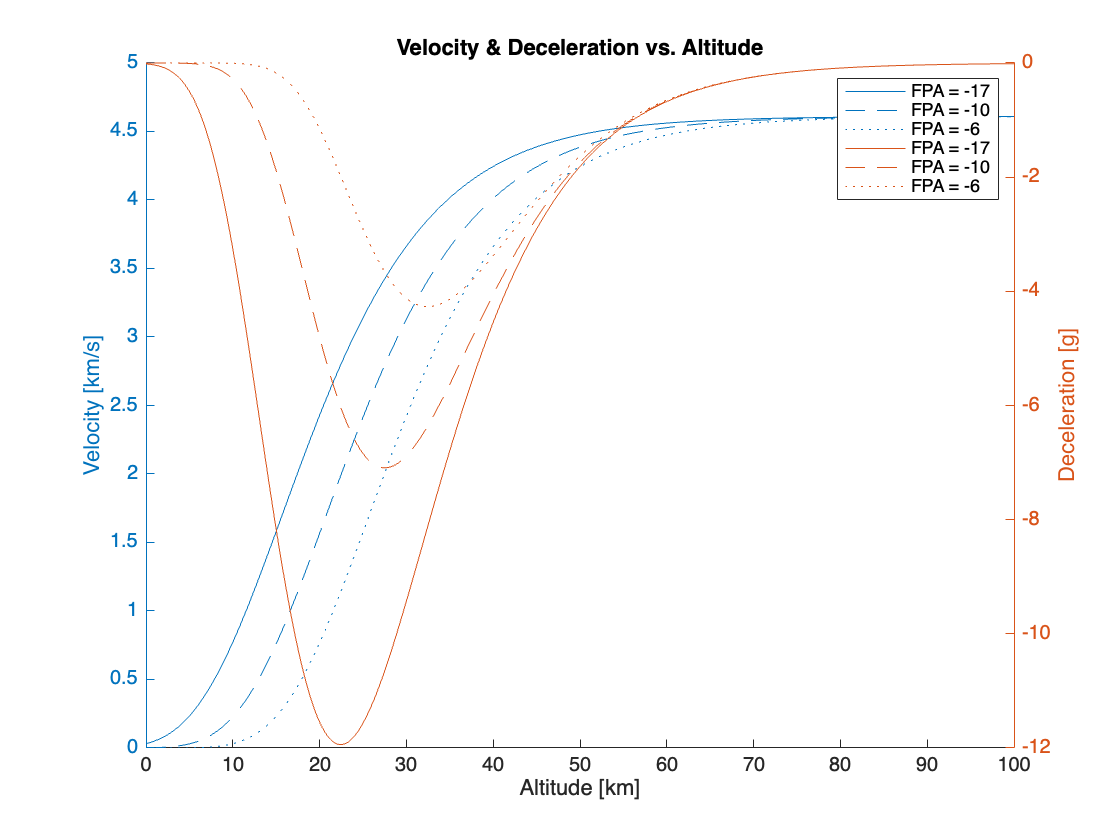

P = 651.8; %Pa
T = (-120 - 32)*5/9 + 273.15; %K
g = 3.71; %m/s^2
M = 0.9532*M_CO2 + 0.027*M_N2 + 0.016*M_AR; %kg/mol
H = R*T/(M*g); %m
A = 1/H; %1/m
rho0 = P*M/(R*T); %kg/m^3

Ve = 4.61e3; %m/s
m = 980; %kg
Cd = 1.65; %-
d = 3.54; %m
beta = m/(Cd*pi/4*d^2); %kg/m^2

h = linspace(0,100,1000); %km
figure();
hold on
for gamma = [-17 -10 -6]
    C = rho0/(2*beta*A*sind(gamma));
    V = Ve*exp(C*exp(-A*h*1000));
    n = -Ve^2/g_earth*sind(gamma)*C*A*exp(2*C*exp(-A*h*1000)).*exp(-A*h*1000);
    yyaxis left
    plot(h,V/1000)
    yyaxis right
    plot(h,n)
end
xlabel('Altitude [km]')
yyaxis left
ylabel('Velocity [km/s]')
yyaxis right
ylabel('Deceleration [g]')
title('Velocity & Deceleration vs. Altitude')
legend('FPA = -17', 'FPA = -10', 'FPA = -6', 'FPA = -17', 'FPA = -10', 'FPA = -6')
hold off

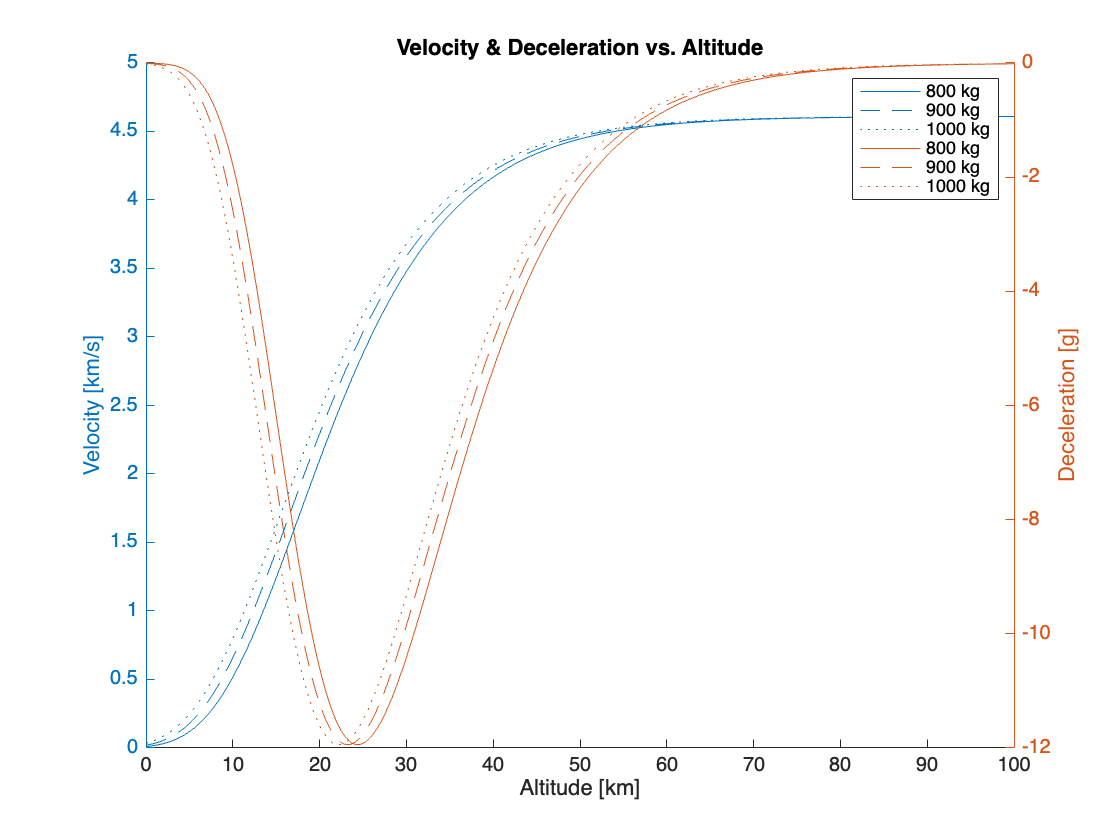

gamma = -17; %deg
h = linspace(0,100,1000); %km
figure();
hold on
for m = [800 900 1000]
    beta = m/(Cd*pi/4*d^2); %kg/m^2
    C = rho0/(2*beta*A*sind(gamma));
    V = Ve*exp(C*exp(-A*h*1000));
    n = -Ve^2/g_earth*sind(gamma)*C*A*exp(2*C*exp(-A*h*1000)).*exp(-A*h*1000);
    yyaxis left
    plot(h,V/1000)
    yyaxis right
    plot(h,n)
end
xlabel('Altitude [km]')
yyaxis left
ylabel('Velocity [km/s]')
yyaxis right
ylabel('Deceleration [g]')
title('Velocity & Deceleration vs. Altitude')
legend('800 kg', '900 kg', '1000 kg', '800 kg', '900 kg', '1000 kg')
hold off